# 动态范围数据后处理

- 导入数据文件Dynamic_Range.xlsx；

- 根据数据绘图并添加注释；

clear
File = "Dynamic_Range.xlsx";
T = readtable(File, 'ReadRowNames',false);

## 查看导入数据

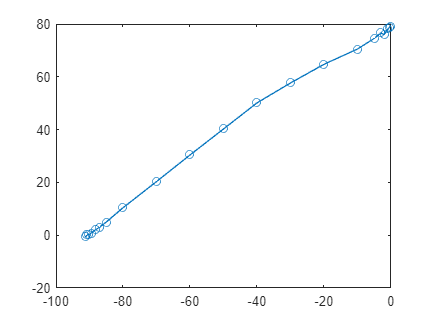

figure
plot(T.dBFS_dB_, T.SINAD_dB_, '-o');

## 利用前半部分数据进行拟合

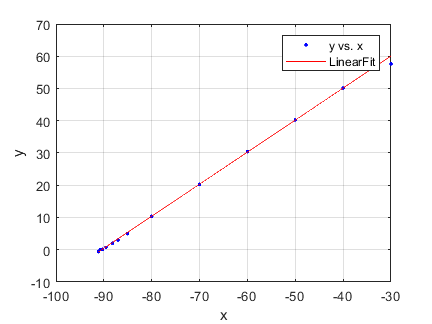

xdata = T.dBFS_dB_(9:end);
ydata = T.SINAD_dB_(9:end);
[fitresult, gof] = createFit(xdata, ydata);


SINAD_dB_fit = T.dBFS_dB_*fitresult.p1 + fitresult.p2;


## 绘制结果图

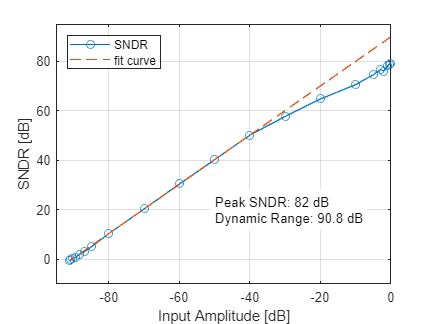

figure
plot(T.dBFS_dB_, T.SINAD_dB_, '-o', T.dBFS_dB_, SINAD_dB_fit, '--');

xlim([-95, 0])
ylim([-10, 95]);
grid on;
xlabel('Input Amplitude [dB]');
ylabel('SNDR [dB]');

legend(["SNDR"; "fit curve"], 'Location','northwest')

text_str = {'Peak SNDR: 82 dB', 'Dynamic Range: 90.8 dB'};

t1 = text(-50,20,text_str, 'HorizontalAlignment','left');
t1.BackgroundColor = [1,1,1];

% t1.FontName
% t1.EdgeColor =[0 0.4470 0.7410];

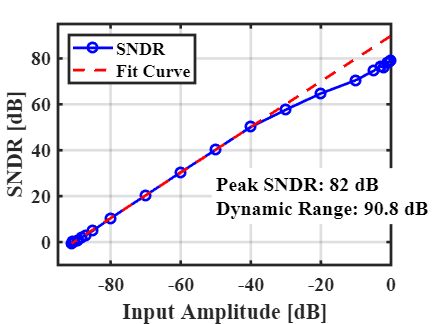

createfigure_DR(T.dBFS_dB_, [T.SINAD_dB_, SINAD_dB_fit])